close all hidden;
clearvars -except;
clc;

rng(418);                       %seed for reproducibility

## **PS 3 implementation**

A_design = [1 0.1; -0.1 0.96];
B_design = [0; 0.1];
C = [1 0];

nx = 2; ny = 1; nu = 1;
Ts = 0.1;
simT = 20;
Nsim = simT / Ts;

r_mag = 5;
ref = r_mag * ones(Nsim + 40, 1);  % extended for horizon


function [F, H, Phi, S] = buildPredictionMatrices(A, B, C, Np, Nc)
    ny = size(C,1);
    nu = size(B,2);
    nx = size(A,1);

    % F matrix
    F = zeros(Np*ny, nx);
    Ap = A;
    for k = 1:Np
        F(k,:) = C * Ap;
        Ap = Ap*A;
    end

    % H matrix
    H = zeros(Np*ny, Nc*nu);
    for i = 1:Np
        for j = 1:Nc
            row = (i-1)*ny + 1 : i*ny;
            col = (j-1)*nu + 1 : j*nu;

            if j <= i-1
                Aexp = A^(i-j);
                H(row,col) = C*Aexp*B;
            elseif j == i
                H(row,col) = C*B;
            end
        end
    end

    % S matrix
    S = tril(ones(Nc));

    % Complete prediction matrix
    Phi = H * S;
end


## **a) Unconstrained MPC**

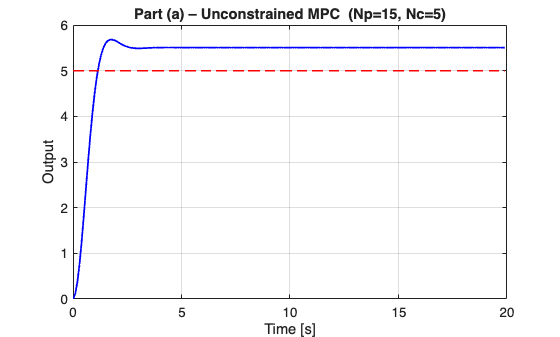

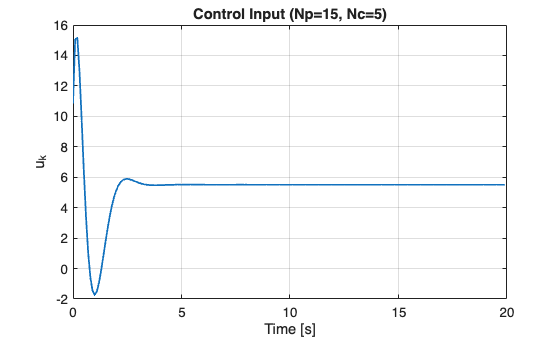

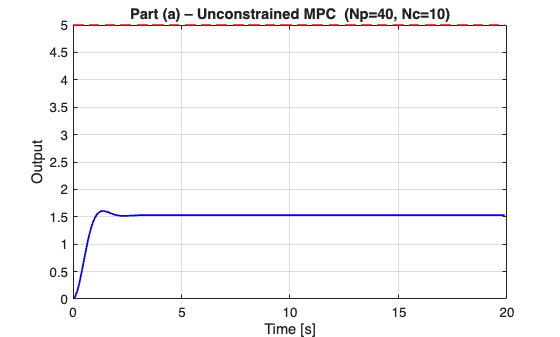

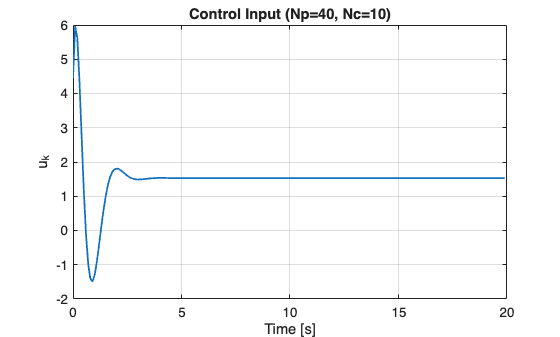


horizon_sets = [15 5; 40 10];   % (Np, Nc) pairs
results_a = struct();

for h = 1:size(horizon_sets,1)

    Np = horizon_sets(h,1);
    Nc = horizon_sets(h,2);
    [F, H, Phi, S] = buildPredictionMatrices(A_design, B_design, C, Np, Nc);
    Qbar = eye(Np);
    Rbar = 0.1 * eye(Nc);

    x = [0;0];
    u_prev = 0;
    ylog = zeros(Nsim,1);
    ulog = zeros(Nsim,1);

    for k = 1:Nsim
        ub = u_prev * ones(Nc,1);
        bk = F*x + H*ub;

        r_window = ref(k:k+Np-1);

        Hqp = Phi'*Qbar*Phi + Rbar;
        Hqp = 0.5*(Hqp + Hqp');  % enforce symmetry

        fqp = Phi'*Qbar*(bk - r_window);

        dU = quadprog(Hqp, fqp, [], [], [], [], [], [], [], ...
                      optimoptions('quadprog','Display','none'));

        u_k = u_prev + dU(1);

        % Apply to plant
        x = A_design*x + B_design*u_k;

        ylog(k) = C*x;
        ulog(k) = u_k;

        u_prev = u_k;
    end

    figure;
    plot(Ts*(0:Nsim-1), ylog, 'b', 'LineWidth', 1.3); hold on;
    stairs(Ts*(0:Nsim-1), ref(1:Nsim), 'r--', 'LineWidth', 1.1);
    title(sprintf('Part (a) – Unconstrained MPC  (Np=%d, Nc=%d)',Np,Nc));
    xlabel('Time [s]'); ylabel('Output');
    grid on;

    figure;
    plot(Ts*(0:Nsim-1), ulog, 'LineWidth', 1.3);
    title(sprintf('Control Input (Np=%d, Nc=%d)',Np,Nc));
    xlabel('Time [s]'); ylabel('u_k');
    grid on;

end

The two horizon selections show a clear trade off. With Np=15, Nc=5, the controller reacts aggressively: the input shows a large initial peak, leading to fast rise time but high control effort and overshoot. With Np=40, Nc=10, the controller behaves much more conservatively: the input remains small and smooth, but the system settles far below the reference, resulting in poor tracking. Thus, shorter horizons yield better tracking but expensive control, while longer horizons reduce input effort at the cost of steady state accuracy.

## **b) Constrained MPC**

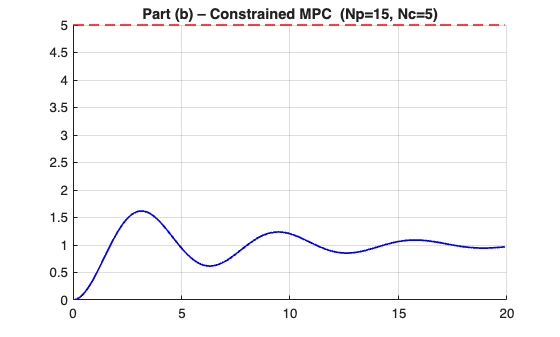

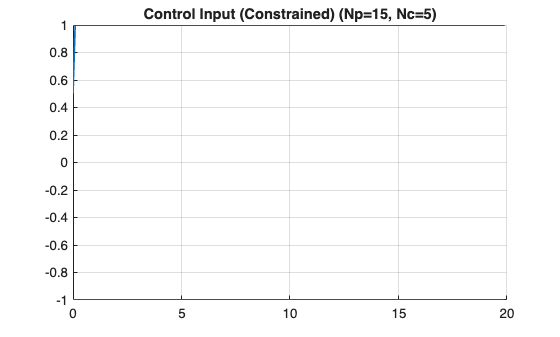

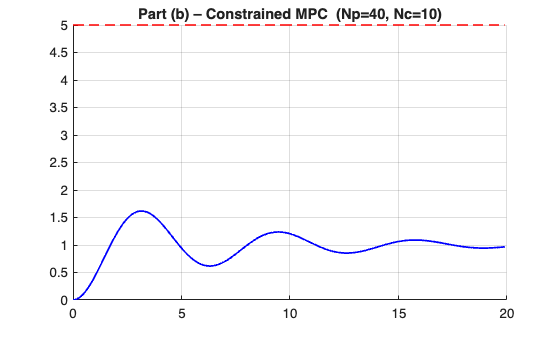

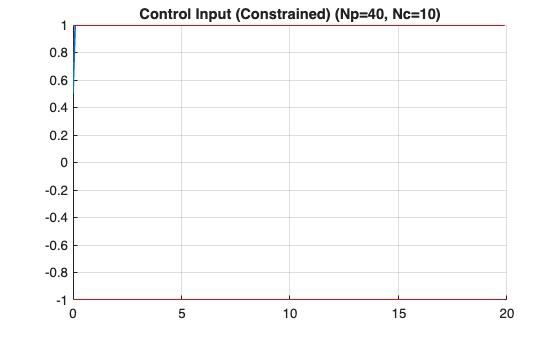


results_b = struct();

for h = 1:size(horizon_sets,1)

    Np = horizon_sets(h,1);
    Nc = horizon_sets(h,2);

    [F, H, Phi, S] = buildPredictionMatrices(A_design, B_design, C, Np, Nc);

    Qbar = eye(Np);
    Rbar = 0.1 * eye(Nc);

    umax = 1;
    dumax = 0.5;

    x = [0;0];
    u_prev = 0;

    ylog = zeros(Nsim,1);
    ulog = zeros(Nsim,1);

    for k = 1:Nsim
        ub = u_prev*ones(Nc,1);
        bk = F*x + H*ub;

        r_window = ref(k:k+Np-1);

        Hqp = Phi'*Qbar*Phi + Rbar;
        Hqp = 0.5*(Hqp + Hqp');
        fqp = Phi'*Qbar*(bk - r_window);

        % Constraints
        A_du = [ eye(Nc); -eye(Nc) ];
        b_du = dumax * ones(2*Nc,1);
        A_u = [ S; -S ];
        b_u = [ umax*ones(Nc,1) - ub;
                umax*ones(Nc,1) + ub ];

        Aineq = [A_du; A_u];
        bineq = [b_du; b_u];

        dU = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], ...
                      optimoptions('quadprog','Display','none'));

        u_k = u_prev + dU(1);

        x = A_design*x + B_design*u_k;

        ylog(k) = C*x;
        ulog(k) = u_k;
        u_prev = u_k;
    end

    
    figure; hold on;
    plot(Ts*(0:Nsim-1), ylog,'b','LineWidth',1.3);
    stairs(Ts*(0:Nsim-1), ref(1:Nsim),'r--','LineWidth',1.1);
    title(sprintf('Part (b) – Constrained MPC  (Np=%d, Nc=%d)',Np,Nc));
    grid on;

    figure; hold on;
    plot(Ts*(0:Nsim-1), ulog,'LineWidth',1.3);
    stairs(Ts*(0:Nsim-1), umax*ones(Nsim,1),'r');
    stairs(Ts*(0:Nsim-1), -umax*ones(Nsim,1),'r');
    title(sprintf('Control Input (Constrained) (Np=%d, Nc=%d)',Np,Nc));
    grid on;

end

When actuator limits are applied, the MPC controller saturates at u=1 almost immediately and remains at this limit for several seconds. Because the plant requires a much larger control effort to reach the reference of 5, the constrained controller is unable to generate sufficient input, and the output settles around 1 instead of tracking the desired value. The rate constraintfurther restricts the controller from making corrections, producing the oscillatory behavior observed in the output. Both horizon sets yield nearly identical responses, since the saturation dominates the closed loop behavior.

## **c) Increasing mass plant**

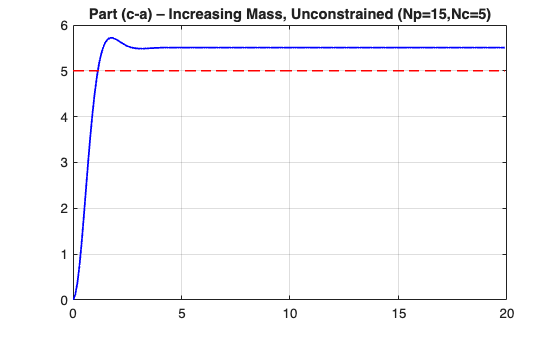

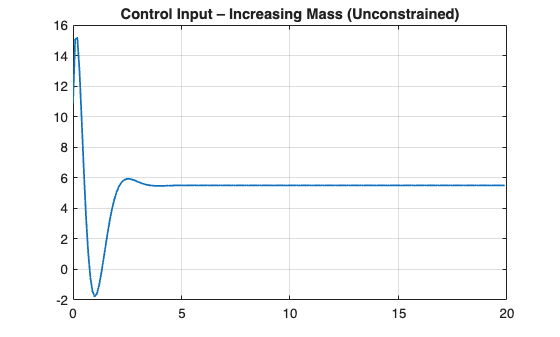

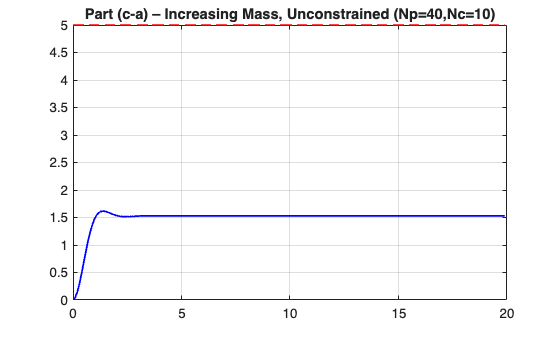

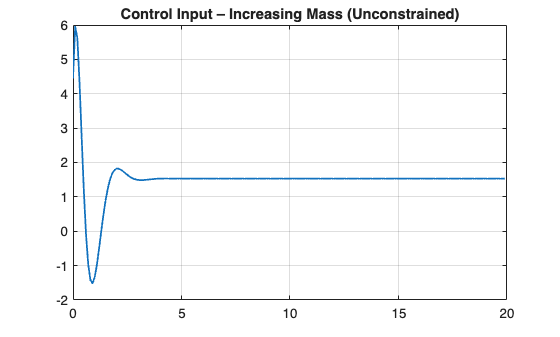

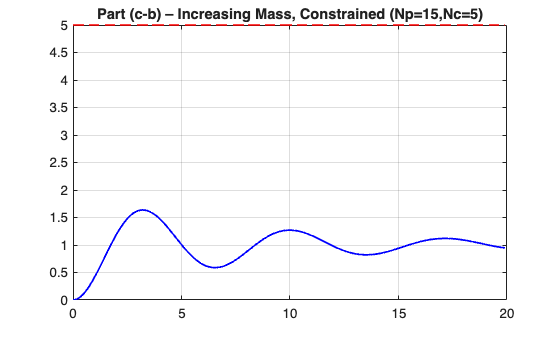

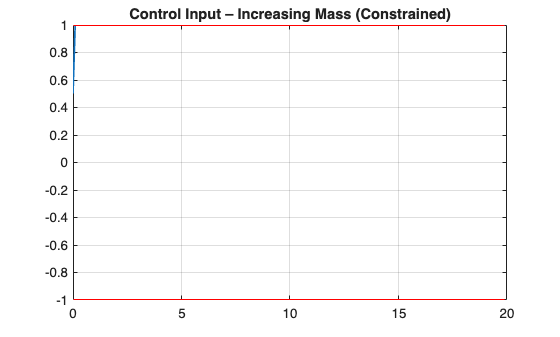

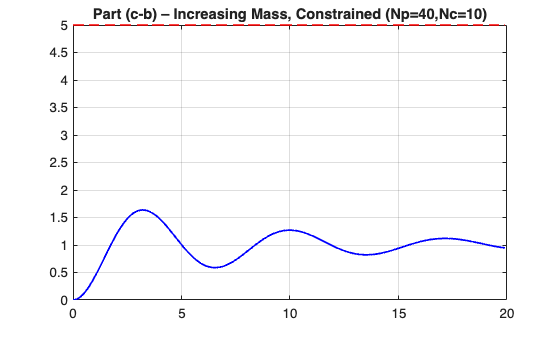


results_c = struct();

for mode = 1:2   % 1 = unconstrained, 2 = constrained

    for h = 1:size(horizon_sets,1)
        Np = horizon_sets(h,1);
        Nc = horizon_sets(h,2);

        [F, H, Phi, S] = buildPredictionMatrices(A_design, B_design, C, Np, Nc);

        Qbar = eye(Np);
        Rbar = 0.1 * eye(Nc);

        umax = 1;
        dumax = 0.5;

        x = [0;0];
        u_prev = 0;
        ylog = zeros(Nsim,1);
        ulog = zeros(Nsim,1);

        for k = 1:Nsim

            % Mass change
            t = k*Ts;
            m = 1 + log(1 + t/40);
            A_true = [1 0.1; -0.1/m, 1 - 0.04/m];
            B_true = [0; 0.1/m];

            ub = u_prev * ones(Nc,1);
            bk = F*x + H*ub;
            r_window = ref(k:k+Np-1);

            Hqp = Phi'*Qbar*Phi + Rbar;
            Hqp = 0.5*(Hqp + Hqp');
            fqp = Phi'*Qbar*(bk - r_window);

            if mode == 1  % unconstrained
                dU = quadprog(Hqp, fqp, [], [], [], [], [], [], [], ...
                               optimoptions('quadprog','Display','none'));
            else
                % constrained
                A_du = [eye(Nc); -eye(Nc)];
                b_du = dumax*ones(2*Nc,1);

                A_u = [S; -S];
                b_u = [umax*ones(Nc,1) - ub;
                       umax*ones(Nc,1) + ub];

                Aineq = [A_du; A_u];
                bineq = [b_du; b_u];

                dU = quadprog(Hqp, fqp, Aineq, bineq, [], [], [], [], [], ...
                              optimoptions('quadprog','Display','none'));
            end

            u_k = u_prev + dU(1);

            x = A_true*x + B_true*u_k;

            ylog(k) = C*x;
            ulog(k) = u_k;
            u_prev = u_k;
        end



        figure;
        plot(Ts*(0:Nsim-1), ylog, 'b','LineWidth',1.3); hold on;
        stairs(Ts*(0:Nsim-1), ref(1:Nsim),'r--','LineWidth',1.1);
        if mode==1
            title(sprintf('Part (c-a) – Increasing Mass, Unconstrained (Np=%d,Nc=%d)',Np,Nc));
        else
            title(sprintf('Part (c-b) – Increasing Mass, Constrained (Np=%d,Nc=%d)',Np,Nc));
        end
        grid on;

        figure;
        plot(Ts*(0:Nsim-1), ulog,'LineWidth',1.3); hold on;
        if mode==2
            stairs(Ts*(0:Nsim-1), umax*ones(Nsim,1),'r');
            stairs(Ts*(0:Nsim-1), -umax*ones(Nsim,1),'r');
        end
        if mode==1
            title(sprintf('Control Input – Increasing Mass (Unconstrained)'));
        else
            title(sprintf('Control Input – Increasing Mass (Constrained)'));
        end
        grid on;

    end
end

When the true plant mass increases over time, the system becomes less responsive to the same control input. Since the MPC is still designed using the PS3 model, it consistently overestimates the plant’s authority, leading to noticeable degradation in tracking performance.

In the unconstrained case, the controller initially behaves exactly as in part (a). With Np=15, Nc=5, it applies a large initial input and achieves fast rise and overshoot. As mass increases, the closed loop still reaches the reference but settles slightly slower, since more input is required to counteract the heavier plant. With Np=40, Nc=10, the conservative controller again produces a small input, and because the plant is even slower the output remains well below 2, showing severe steady state error. The mismatch amplifies the already poor tracking observed in part (a).

In the constrained case, the effect is more solid. The true plant requires even larger control effort due to increased mass, but the actuator saturates at u = 1 and quickly becomes the limiting factor. As a result, the output exhibits the same oscillatory, under driven behaviour as in part (b), but with even weaker response. The horizon length has almost no influence because saturation dominates the closed loop dynamics.

Overall, increasing the mass introduces a model mismatch that reduces tracking quality in both scenarios. The unconstrained controller remains functional but less accurate, while the constrained controller becomes entirely input limited and cannot track the reference at all.